Test 9 - Balahura Vlad grupa 231/1

Problema 9. 

f = @(x) 1 + sin(exp(3*x));
a = -1;
b = 1;
err = 5e-6;

[Q_ad, iter_ad] = adquad2_count(f, a, b, err);
fprintf('--- Cuadratura Adaptiva ---\n');

--- Cuadratura Adaptiva ---


fprintf('Valoare integrală: %.10f\n', Q_ad);

Valoare integrală: 2.5008091097


fprintf('Numar apeluri recursive: %d\n\n', iter_ad);

Numar apeluri recursive: 195




[Q_romb, iter_romb] = romberg_tol(f, a, b, err);
fprintf('--- Metoda Romberg ---\n');

--- Metoda Romberg ---


fprintf('Valoare integrala: %.10f\n', Q_romb);

Valoare integrala: 2.5008088101


fprintf('Numar iteratii (linii in matricea Romberg): %d\n', iter_romb);

Numar iteratii (linii in matricea Romberg): 9


Metoda cuadraturii adaptive subîmparte recursiv intervalul de integrare în funcție de o estimare locală a erorii. La fiecare pas, se compară aproximarea integralei folosind regula lui Simpson pe întregul interval ($$Q_1$$) cu aproximarea obținută prin aplicarea regulii lui Simpson pe cele două jumătăți ale intervalului ($$Q_2$$). Când diferența dintre ele scade sub toleranța impusă, se aplică extrapolarea Richardson pentru a returna o valoare și mai precisă

function [Q, steps] = adquad2_count(f, a, b, err, fa, fc, fb)
    if nargin < 5
        fa = f(a); 
        fc = f((a+b)/2); 
        fb = f(b);
    end
    h = b - a; 
    c = (a + b) / 2;
    fd = f((a + c) / 2); 
    fe = f((c + b) / 2);
    
    Q1 = h/6 * (fa + 4*fc + fb);
    Q2 = h/12 * (fa + 4*fd + 2*fc + 4*fe + fb);
    
    if abs(Q1 - Q2) < err
        Q = Q2 + (Q2 - Q1) / 15;
        steps = 1; 
    else
   
        [Q_left, s1] = adquad2_count(f, a, c, err/2, fa, fd, fc);
        [Q_right, s2] = adquad2_count(f, c, b, err/2, fc, fe, fb);
        Q = Q_left + Q_right;
        steps = s1 + s2 + 1; 
    end
end

Metoda lui Romberg evaluează integrala generând un tabel triunghiular. Prima coloană conține aproximări obținute cu regula repetată a trapezului, înjumătățind pasul la fiecare linie. Restul coloanelor folosesc extrapolarea Richardson pentru a elimina succesiv termenii de eroare, obținând reguli de cuadratură de ordin superior (Simpson, Boole, etc.). Condiția de oprire verifică diferența dintre ultimele două elemente de pe diagonala principală a tabelului.

Formula de extrapolare: $$$T_{i,j} = \frac{4^{j-1} T_{i, j-1} - T_{i-1, j-1}}{4^{j-1} - 1}$$$

Condiția de convergență: $$$|T_{i,i} - T_{i-1,i-1}| < \varepsilon$$$

function [val, n_iter] = romberg_tol(f, a, b, err)
    MAX_ITER = 25; 
    T = NaN(MAX_ITER, MAX_ITER);
    
    for i = 1:MAX_ITER
        T(i,1) = reptrapezium(f, a, b, 2^(i-1));
        for j = 2:i
           
            T(i,j) = (4^(-j+1)*T(i-1,j-1) - T(i,j-1)) / (4^(-j+1) - 1);
        end
        
   
        if i > 1 && abs(T(i,i) - T(i-1,i-1)) < err
            val = T(i,i);
            n_iter = i;
            return;
        end
    end
    val = T(MAX_ITER, MAX_ITER);
    n_iter = MAX_ITER;
    warning('Metoda Romberg nu a convers in numarul maxim de iteratii permis.');
end

Aceasta este formula compusă de bază (Newton-Cotes închisă de ordin 1). Funcția împarte intervalul $$[a, b]$$ în $$n$$ subintervale egale de lungime$ $h$$ și aproximează aria de sub curba funcției printr-o sumă de trapeze.

function I = reptrapezium(f, a, b, n)
    h = (b - a) / n;
    x = a:h:b;
    I = (h / 2) * (f(x(1)) + 2*sum(f(x(2:end-1))) + f(x(end)));
end

Problema 10

 a) În metoda Romberg, prima coloană reprezintă regula repetată a trapezului. Fie un interval de bază $$[0, h]$$. Avem:

- Aproximarea cu pasul h: $$$R_{i,1} = \frac{h}{2}[f(0)+f(h)]$$$

- Aproximarea cu pasul $$h/2$$: $$$R_{i+1,1} = \frac{h}{4}[f(0)+2f(h/2)+f(h)]$$$

Extrapolarea Richardson pentru coloana a doua elimină eroarea de ordinul $$O(h^2)$:$


$$$$R_{i+1,2} = \frac{4R_{i+1,1}-R_{i,1}}{3}$$$$


Înlocuind expresiile de mai sus:


$$$$R_{i+1,2} = \frac{h[f(0)+2f(h/2)+f(h)] - \frac{h}{2}[f(0)+f(h)]}{3}$$$$



$$$R_{i+1,2} = \frac{h \cdot \frac{1}{2}f(0) + 2hf(h/2) + h \cdot \frac{1}{2}f(h)}{3}$$$$



$$$$R_{i+1,2} = \frac{h/2}{3}[f(0)+4f(h/2)+f(h)]$$ $$


Este formula regulii lui Simpson aplicată pe intervalul $$[0, h]$$ cu pasul $$\frac{h}{2}$$. Prin adunarea acestor sub-intervale pe întreg domeniul $$[a, b]$$, obținem regula repetată a lui Simpson.

b) Coloana a treia din tabelul Romberg se obține extrapolând rezultatele de pe coloana a doua (Simpson, de ordinul $$O(h^4)$$):


$$$$R_{i+2,3}=\frac{16R_{i+2,2}-R_{i+1,2}}{15}$$$$


Să considerăm din nou un singur interval de bază $$[0, h]$$.

Din punctul (a), știm că $$R_{i+1,2} = S(h)$$ (regula Simpson cu punctele $$0, h/2, h$$):


$$$$S(h)=\frac{h/2}{3}[f(0)+4f(h/2)+f(h)]=\frac{h}{6}[f(0)+4f(h/2)+f(h)]$$$$


Pentru $$R_{i+2,2}$$, înjumătățim din nou pasul la$ $h/4$$. Regula Simpson pe același interval $$[0, h]$$ se va aplica de două ori (pe $$[0, h/2]$ și pe $[h/2, h]$$):


$$$$S(h/2)=\frac{h/4}{3}[f(0)+4f(h/4)+2f(h/2)+4f(3h/4)+f(h)]=\frac{h}{12}[f(0)+4f(h/4)+2f(h/2)+4f(3h/4)+f(h)]$$$$


Aplicăm extrapolarea cu factorul 16:


$$$$R_{i+2,3}=\frac{16S(h/2)-S(h)}{15}$$$$



$$$$R_{i+2,3}=\frac{1}{15}\left(\frac{16h}{12}[f(0)+4f(h/4)+2f(h/2)+4f(3h/4)+f(h)]-\frac{2h}{12}[f(0)+4f(h/2)+f(h)]\right)$$$$


Aducem la același numitor și factorizăm $$\frac{h}{12 \cdot 15} = \frac{h}{180}$$:


$$$$R_{i+2,3}=\frac{h}{180}\left(16[f_0+4f_{1/4}+2f_{1/2}+4f_{3/4}+f_1]-2[f_0+4f_{1/2}+f_1]\right)$$$$



$$$$R_{i+2,3}=\frac{h}{180}[14f_0+64f_{1/4}+24f_{1/2}+64f_{3/4}+14f_1]$$$$


Împărțim prin 2:


$$$$R_{i+2,3}=\frac{h}{90}[7f_0+32f_{1/4}+12f_{1/2}+32f_{3/4}+7f_1]$$$$


Aceasta este exact varianta elementară a regulii Boole-Villarceau.

c)

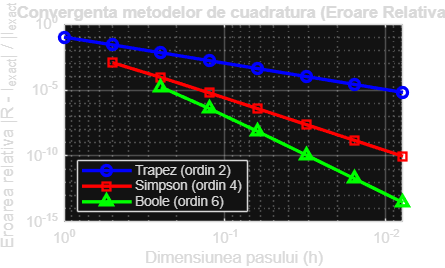

f = @(x) log(x);
a = 1; 
b = 2;
I_exact = 2*log(2) - 1;

n_iter = 8; 


T = romberg(f, a, b, n_iter);

h = NaN(n_iter, 1);
for i = 1:n_iter
    h(i) = (b-a) / (2^(i-1));
end

Err_Trapez  = abs(T(:,1) - I_exact) / abs(I_exact);
Err_Simpson = abs(T(:,2) - I_exact) / abs(I_exact);
Err_Boole   = abs(T(:,3) - I_exact) / abs(I_exact);

figure('Name', 'Eroarea relativa in functie de pasul h', 'Color', 'w');


loglog(h, Err_Trapez, 'b-o', 'LineWidth', 2, 'MarkerSize', 6); hold on;
loglog(h(2:end), Err_Simpson(2:end), 'r-s', 'LineWidth', 2, 'MarkerSize', 6);
loglog(h(3:end), Err_Boole(3:end), 'g-^', 'LineWidth', 2, 'MarkerSize', 6);

grid on;
set(gca, 'XDir', 'reverse'); 
xlabel('Dimensiunea pasului (h)'); 
ylabel('Eroarea relativa |R - I_{exact}| / |I_{exact}|');
title('Convergenta metodelor de cuadratura (Eroare Relativa)');

legend('Trapez (ordin 2)', 'Simpson (ordin 4)', 'Boole (ordin 6)', 'Location', 'southwest');




--- Tabel Romberg partial (Problema 10 c) ---


fprintf('\n--- Tabel Romberg partial (Problema 10 c) ---\n');

  i |    h     |   Trapez (O(h^2)) |  Simpson (O(h^4)) |   Boole (O(h^6))  


fprintf('  i |    h     |   Trapez (O(h^2)) |  Simpson (O(h^4)) |   Boole (O(h^6))  \n');

---------------------------------------------------------------------------


fprintf('---------------------------------------------------------------------------\n');

for i = 1:n_iter
    
    if i < 2, str_simp = '        -        '; else, str_simp = sprintf('%17.10f', T(i,2)); end
    if i < 3, str_boole = '        -        '; else, str_boole = sprintf('%17.10f', T(i,3)); end

    fprintf('%3d | %8.4f | %17.10f | %s | %s\n', i, h(i), T(i,1), str_simp, str_boole);
end

  1 |   1.0000 |      0.3465735903 |         -         |         -        
  2 |   0.5000 |      0.3760193492 |      0.3858346022 |         -        
  3 |   0.2500 |      0.3836995094 |      0.3862595628 |      0.3862878935
  4 |   0.1250 |      0.3856439100 |      0.3862920435 |      0.3862942088
  5 |   0.0625 |      0.3861316377 |      0.3862942137 |      0.3862943584
  6 |   0.0312 |      0.3862536733 |      0.3862943519 |      0.3862943611
  7 |   0.0156 |      0.3862841887 |      0.3862943605 |      0.3862943611
  8 |   0.0078 |      0.3862918180 |      0.3862943611 |      0.3862943611



function T = romberg(f, a, b, n)
T = NaN(n);
for i = 1:n
    T(i,1) = reptrapezium(f, a, b, 2^(i-1));
    for j = 2:i
        T(i,j) = (4^(-j+1)*T(i-1,j-1) - T(i,j-1)) / (4^(-j+1) - 1);
    end
end
end